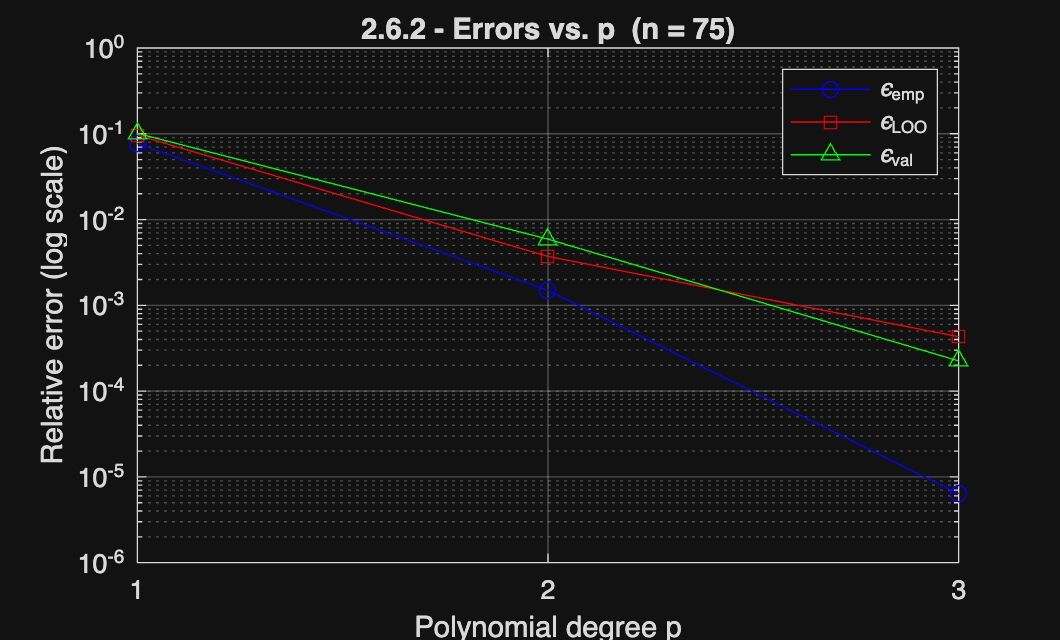

M = numel(params);
n = 15 * M;

[X_ED, Y_ED] = sampleED(n, params, @riverDischarge);
Xi_ED     = isoTransform(X_ED, params);

% Reference moments for 2.6.3
mu_ref  = mean(Y_val);
var_ref = var(Y_val);

% Storage for 2.6.2
p_vals    = [];
eps_emp_v = [];
eps_loo_v = [];
eps_val_v = [];

% Storage for 2.6.3
err_mu_v  = [];
err_var_v = [];

for p = 1:10
    alphas = create_alphas(M, p);
    P_card = size(alphas, 1);
    
    % Stop when P >= n (OLS breaks down, Lecture 8 Slide 9)
    if P_card >= n
        break;
    end
    
    % Build PCE (shared for both 2.6.2 and 2.6.3)
    Psi       = buildPsi(Xi_ED, alphas, params);
    c         = computeCoeffs(Psi, Y_ED);
    Y_PCE_val = evalPCE(X_val, c, alphas, params);
    
    %% 2.6.2 - Global errors
    [ee, el, ev] = computeErrors(Psi, Y_ED, c, Y_val, Y_PCE_val);
    
    %% 2.6.3 - Moments from coefficients (orthonormality property)
    % mean = constant term c(1)
    % var  = sum of squared non-constant coefficients
    mu_PCE  = c(1);
    var_PCE = sum(c(2:end).^2);
    
    % Store results
    p_vals(end+1)    = p;
    eps_emp_v(end+1) = ee;
    eps_loo_v(end+1) = el;
    eps_val_v(end+1) = ev;
    err_mu_v(end+1)  = abs(mu_PCE  / mu_ref  - 1);
    err_var_v(end+1) = abs(var_PCE / var_ref - 1);
end

%% 2.6.2 - Plot errors vs. p
figure;
semilogy(p_vals, eps_emp_v, 'b-o'); hold on;
semilogy(p_vals, eps_loo_v, 'r-s');
semilogy(p_vals, eps_val_v, 'g-^'); hold off;
xlabel('Polynomial degree p');
ylabel('Relative error (log scale)');
title(sprintf('2.6.2 - Errors vs. p  (n = %d)', n));
legend('\epsilon_{emp}', '\epsilon_{LOO}', '\epsilon_{val}');
grid on; xticks(p_vals);

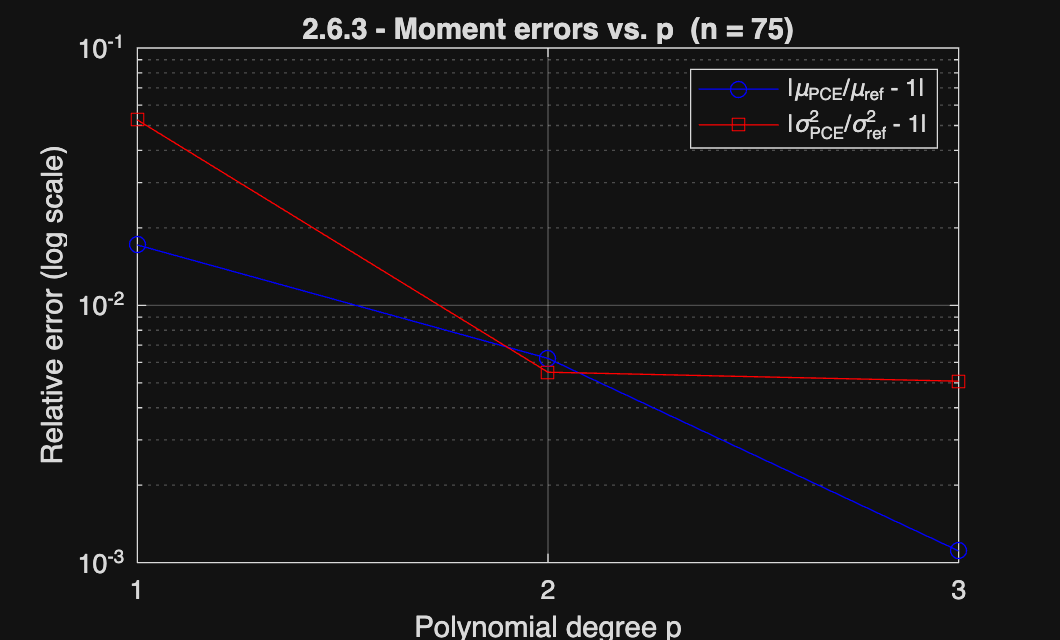


%% 2.6.3 - Plot moment errors vs. p
figure;
semilogy(p_vals, err_mu_v,  'b-o'); hold on;
semilogy(p_vals, err_var_v, 'r-s'); hold off;
xlabel('Polynomial degree p');
ylabel('Relative error (log scale)');
title(sprintf('2.6.3 - Moment errors vs. p  (n = %d)', n));
legend('|\mu_{PCE}/\mu_{ref} - 1|', '|\sigma^2_{PCE}/\sigma^2_{ref} - 1|');
grid on; xticks(p_vals);